# Identificazione in presenza di limitazioni di velocità/posizione massima.

Spesso i sistemi meccanici hanno limiti di posizione e velocità massima.

In questo caso, è necessario lavorare con range positivi e negativi.

Tuttavia la presenza dell'attrito statico rende l'approssimazione lineare molto imprecisa quando si lavora con continui cambi di posizione e velocità.

Una soluzione è inserire una "portante", cioè un segnale a bassa frequenza che consente di mantenere la velocità diverse da zero per lunghi tratti.

## Esempio

consideriamo il modello meccanico motore-trasmissione-carico, con trasmissione elastica e presenza di attrito statico.

Il sistema ha un ingresso (la coppia motore), e due uscite (posizione e velocità motore). Ci interessa trovare un modello lineare che approssima la relazione coppia-velocità.

clc;clear all;close all;
set(0, 'defaultFigurePosition',  [ 1, 1, 800, 600]); % figure più grandi
st=1e-3;
addpath(['..',filesep,'modelli']) %aggiunge al path la cartella modelli (che deve essere nella cartella superiore)
model=ElasticTransmission(st);
model.show;

This system has 2 outputs:
- motor position
- motor velocity
This system has 1 inputs:
- motor torque, with maximum limit = 5.000000


cs=ControlledSystem(model);

Definisco la portante come un segnale sinusoidale a bassa frequenza, con un'ampiezza tale da non sforare i limiti. L'ideale è andare in prossimità dei limiti mantenendo un discreto margine (esempio 70% limiti).

omega_portante=0.05;
ampiezza_portante=0.5;
T_portante=2*pi/omega_portante;

scelgo una lunghezza dell'esperimento di almeno un periodo della portante.

t=(0:st:(1.1*T_portante))';
portante=ampiezza_portante*sin(omega_portante*t);

Dopo di che posso andare a definire il segnale eccitante, che partirà da una frequenza maggiore (almeno un decade).

w0=omega_portante*30; %rad/s
w1=pi/st; %rad/s
control_action_identificazione = chirp(t,w0/2/pi,t(end),w1/2/pi, 'logarithmic');
ampliezza_identificazione=2;

Sommo i due segnali

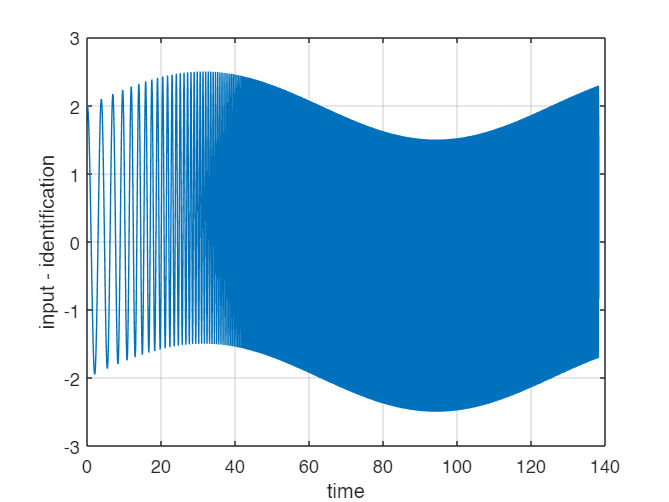

control_action=portante + control_action_identificazione*ampliezza_identificazione;
figure
plot(t,control_action)
xlabel('time')
ylabel('input - identification')
grid on

Spettrogramma (contenuto frequenziale al variare del tempo)

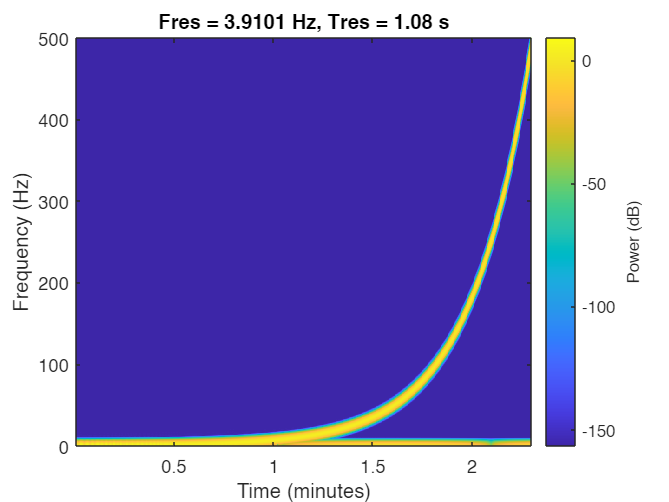

pspectrum(control_action,1/st,'spectrogram');

## Simulazione sistema

I tratti con velocità vicina allo 0 hanno una dinamica chiaramente non lineare, l'approssimazione lineare nelle frequenze esplorare dal segnale eccitante in quei punti sarà scarsa.

cs.initialize
tic
for idx=1:length(t)
    [process_output(idx,:),t(idx,1)]=cs.openloop(control_action(idx));
end
toc

Elapsed time is 128.012365 seconds.


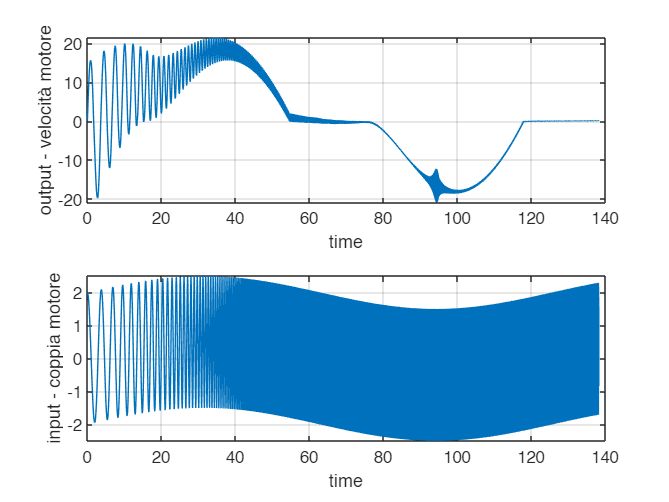


figure(1)
subplot(2,1,1)
plot(t,process_output(:,2))
xlabel('time')
ylabel('output - velocità motore')
grid on

subplot(2,1,2)
plot(t,control_action)
xlabel('time')
ylabel('input - coppia motore')
grid on

Nota: le frequenze in prossimità dei cambi di velocità sono stimate peggio (è opportuno che: 1) ripetere con segnali diversi 2) in validazione il signale sia diverso).

## Identificazione

### Calcolo risposta in frequenza

Definisco l'oggetto identification data (iddata)

identification=iddata(process_output(:,2),control_action,st);

Calcolo la risposta in frequenza con il comando e la plotto

freq_resp_ident = spafdr(identification);
figure(2)
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(freq_resp_ident, bode_opts);
grid on
hold on

Plotto la frequenza di inizio del segnale eccitante

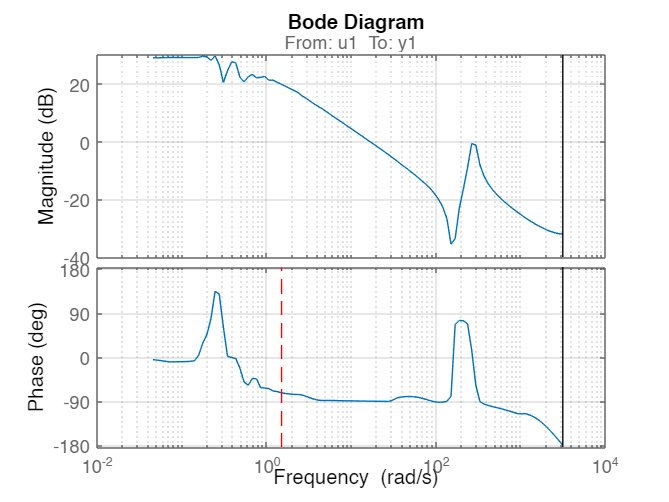

hold on
plot(w0*[1 1],ylim,'--r')
hold off
grid on

La parte a sinistra nella linea tratteggiate non mi interessa (il segnale non ha contribuito informatico apprezzabile ed è "disturbato" dalla presenza dell'attrito statico).

### Stima del modello

devo dire al modello di non considerare le basse frequenze. Creo un vettore di pesi da dare allo stimatore (peso basso, poca importanza).

peso=ones(length(freq_resp_ident.Frequency),1);
wpeso0=10;
wpeso1=2000;
peso(freq_resp_ident.Frequency<wpeso0)=1e-5;
peso(freq_resp_ident.Frequency>wpeso1)=1e-5;

opts=ssestOptions('WeightingFilter',peso,'EnforceStability',1);
modello_continuo = ssest(freq_resp_ident,3,opts);
modello_discreto = ssest(freq_resp_ident,3,'Ts',st,opts);

### Grafico modelli

aggiungo opzione per evitare la molteplicità di 360° nella base

figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';

plotto i dati sperimentali

h=bodeplot(freq_resp_ident, bode_opts);

si può aggiungere l'intervallo di confidenza (in questo caso 3*sigma)

hold on
showConfidence(h,3)

grafico i modelli stimati

bode(modello_continuo,modello_discreto, bode_opts)

visualizzo solo il range di frequenze di interesse

xlim([w0 w1])
plot([wpeso0 wpeso0],ylim,'--k')
plot([wpeso1 wpeso1],ylim,'--k')

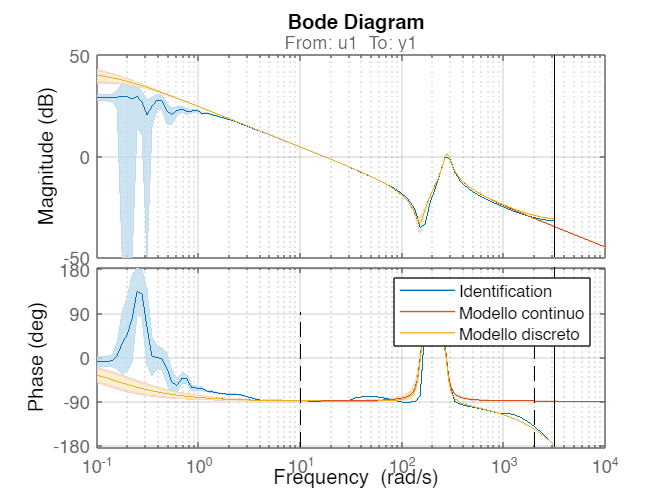

hold off
grid on
xlim([1e-1 1e4])

legend('Identification','Modello continuo','Modello discreto')

## Validazione

Cambio portante e segnale eccitante

omega_portante_v=0.03;
ampiezza_portante_v=3;
T_portante_v=2*pi/omega_portante_v;

scelgo una lunghezza dell'esperimento di almeno un periodo della portante.

t_v=(0:st:(1.1*T_portante_v))';
portante_v=ampiezza_portante_v*sin(2*pi/120*t_v);

Dopo di che posso andare a definire il segnale eccitante, che partirà da una frequenza maggiore (almeno un decade).

w0_v=omega_portante_v*20; %rad/s
w1_v=2000; %rad/s
control_action_validazione = chirp(t_v,w0_v/2/pi,t_v(end),w1_v/2/pi, 'logarithmic');
ampliezza_validazione=1.5;

Sommo i due segnali

control_action_v=portante_v+ control_action_validazione*ampliezza_validazione;

cs.initialize

for idx=1:length(t_v)
    [process_output_v(idx,:),t_v(idx,1)]=cs.openloop(control_action_v(idx));
end

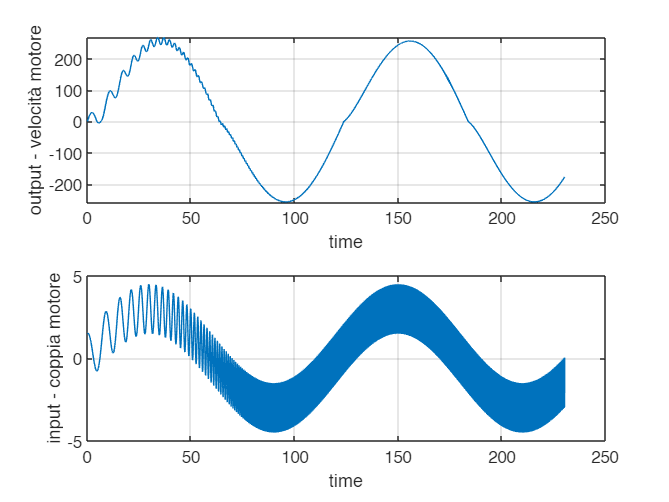

figure
subplot(2,1,1)
plot(t_v,process_output_v(:,2))
xlabel('time')
ylabel('output - velocità motore')
grid on

subplot(2,1,2)
plot(t_v,control_action_v)
xlabel('time')
ylabel('input - coppia motore')
grid on

### Validazione in frequenza

validation=iddata(process_output_v(:,2),control_action_v,st);
freq_resp_vali = spafdr(validation);
figure
bode(freq_resp_vali,freq_resp_ident,bode_opts)

Plotto la frequenza di inizio del segnale eccitante

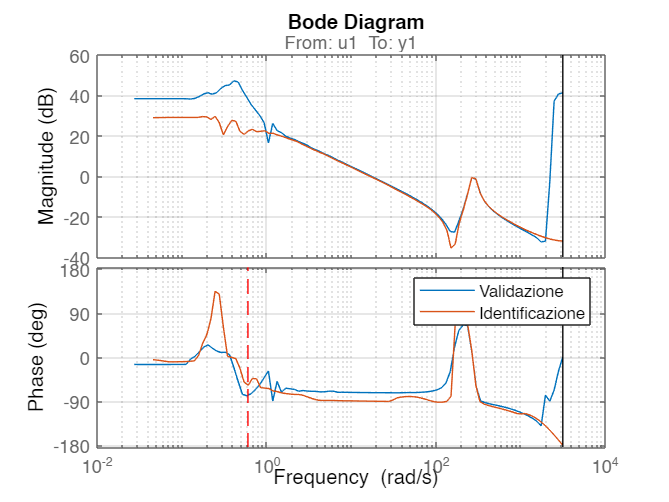

hold on
plot(w0_v*[1 1],ylim,'--r')
hold off
grid on
legend('Validazione','Identificazione')

Grafico diagrammi di Bode

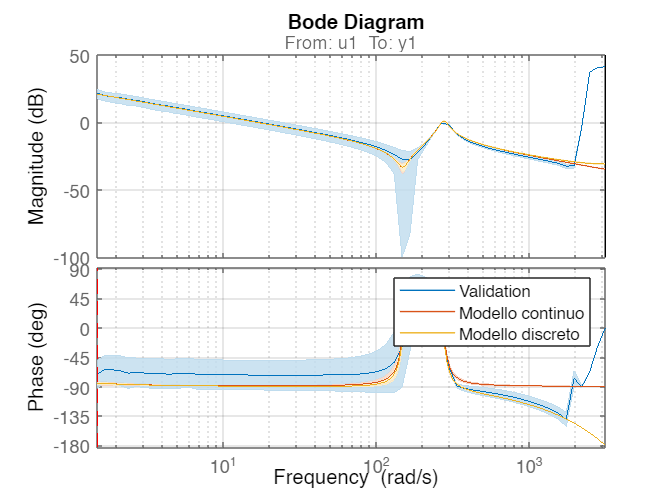

figure
h=bodeplot(freq_resp_vali, bode_opts);
hold on
showConfidence(h,3)
bode(modello_continuo,modello_discreto, bode_opts)
xlim([w0 w1])
plot(w0*[1 1],ylim,'--r')
hold off
grid on

legend('Validation','Modello continuo','Modello discreto')

## Il comando compare

Il comando compare analizza tutto il range di frequenza anche quelli che non ci interessano, per cui non è particolarmente utile.

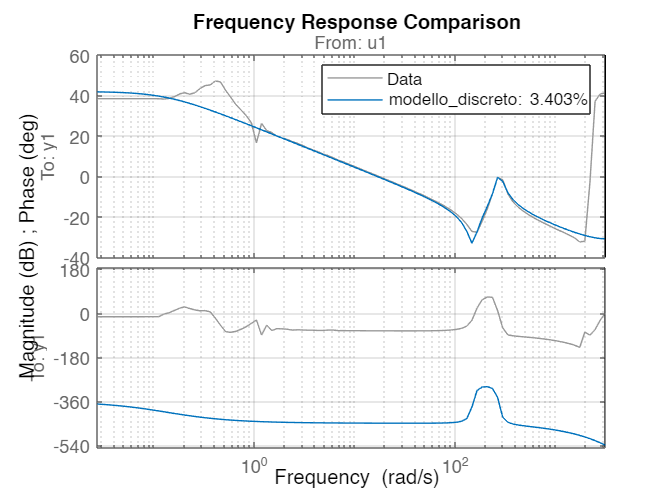

figure 
compare(freq_resp_vali,modello_discreto)
grid on

## La validazione del tempo

abbiamo visto che la stima in bassa frequenza è di bassa qualità, questo fa si che la comparazione fra modello e dati sperimentali nel tempo sia di bassimo livello, ma dal punto di vista del controllo ci interessa poco (a bassa frequenza il controllore è molto robusto a qualsiasi variazione di processo)

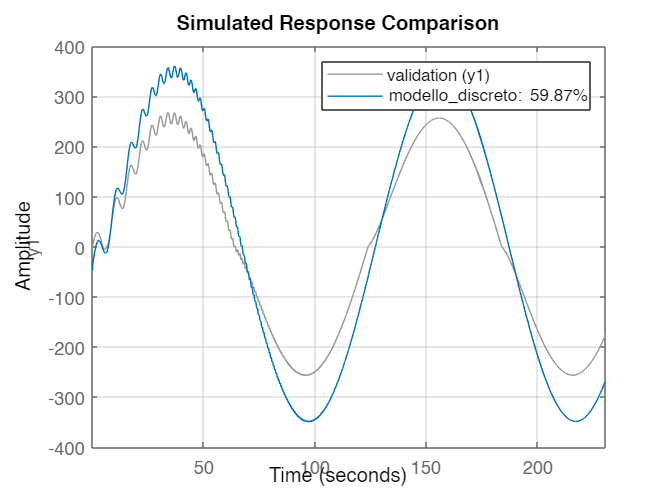

figure 
compare(validation,modello_discreto)
grid on

## Identificazione del tempo e la sua bontà nel tempo e in frequenza

E' possibile stimare il modello nel tempo ma:

- è più facile che l'attrito statico ci mandi fuori strada (provare con ampiezza della portante parti a 2 o pari a 0.5)

- non è possibile concentrarsi su un range di frequenze particolare.

usa_terzo_ordine=false;
if (usa_terzo_ordine)
    modello_discreto_tempo = ssest(identification,3,'Ts',st);
else
    modello_discreto_tempo = ssest(identification,9,'Ts',st);
end

Grafico comparazione del tempo - identificazione

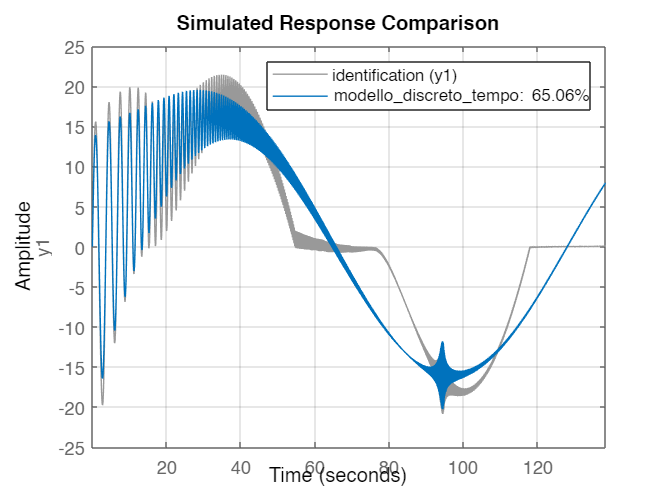

figure
compare(modello_discreto_tempo,identification)
grid on

Grafico comparazione del tempo - validazione

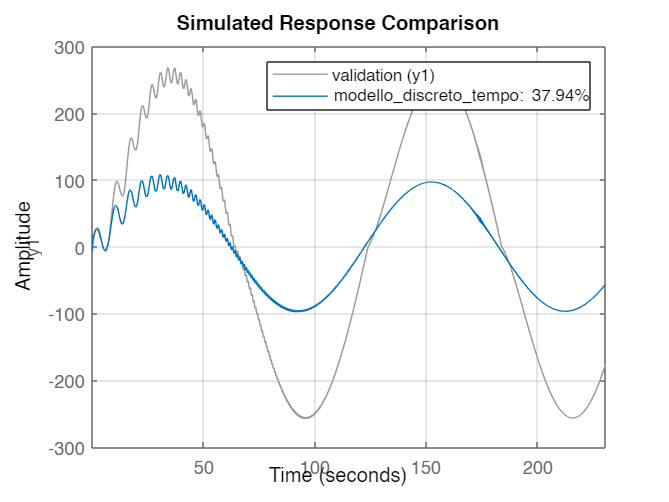

figure
compare(modello_discreto_tempo,validation)
grid on

Diagramma di Bode identificazione

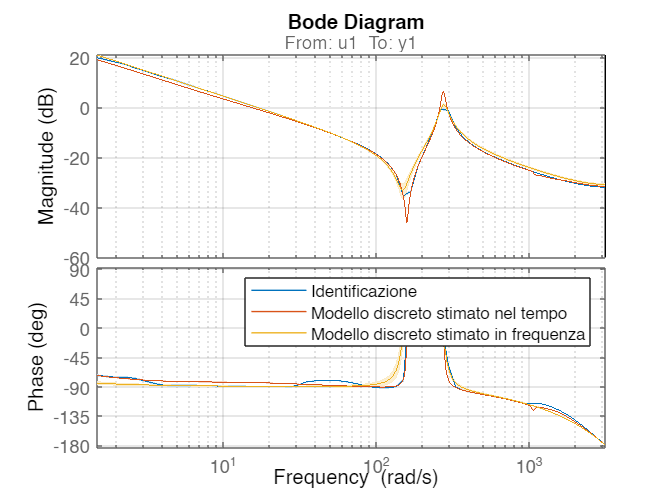

figure
h=bodeplot(freq_resp_ident, bode_opts);
hold on
showConfidence(h,3)
bode(modello_discreto_tempo, bode_opts)
bode(modello_discreto, bode_opts)
xlim([w0 w1])
hold off
grid on

legend('Identificazione','Modello discreto stimato nel tempo','Modello discreto stimato in frequenza')

Diagramma di Bode validazione

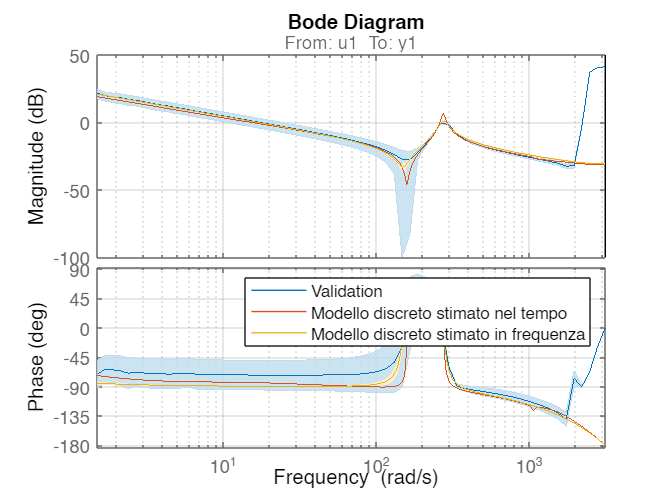

figure
h=bodeplot(freq_resp_vali, bode_opts);
hold on
showConfidence(h,3)
bode(modello_discreto_tempo, bode_opts)
bode(modello_discreto, bode_opts)
xlim([w0 w1])
hold off
grid on

legend('Validation','Modello discreto stimato nel tempo','Modello discreto stimato in frequenza')